x = 286;
alpha = 1 + mod(x,3)

alpha = 2

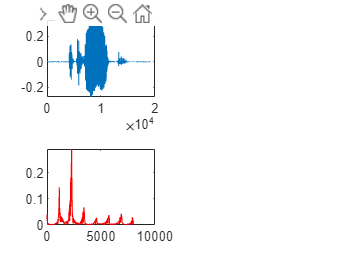


F= 250.*alpha;
data = importdata('speech.wav');
[s,Fs] = audioread('speech.wav');
y1 = fn(s, F, Fs);
T = 1/Fs;
L= 1500;
t=(0:L-1)*T;
y0 = fft(y1);
s0 = fft(s);
f = Fs*(0:(L/2))/L;
P2 = abs(y0/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
Q2 = abs(s0/L);
Q1 = Q2(1:L/2+1);
Q1(2:end-1) = 2*Q1(2:end-1);
subplot(2,2,1);
plot(y1);
subplot(2,2,3);
plot(f, P1, 'blue', f, Q1, 'red');

function y=fn(s, F, Fs)
y= s.*cos(2.*pi.*F./Fs);
end